## Q3 - part a | Output Error

clc; clear;


%%

load q3_402123100.mat

u1_val = u2;
y1_val = y2;

u2_val = u1;
y2_val = y1;


%%
% Guassian Input **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> Guassian Input Identification Begins:------------------------------\n")

>>> Guassian Input Identification Begins:------------------------------


### Guassian Input - PRBS Validation

%%

Ts = 0.1; 
t = 0:Ts:length(u1)*Ts-Ts;
t_val = 0:Ts:length(u1_val)*Ts-Ts;
N = length(y1);
N_val = length(y1_val);

data_guassian = iddata(y1,u1,Ts);

%%


fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nk = 1;
    p = na+nb;
    
    try
        sys = oe(data_guassian, [na nb nk]);
        oe_y_hat_guassian = lsim(sys, u1, t);
    catch
        break
    end

    [r2_oe, mse_oe] = rSQR(y1, oe_y_hat_guassian);

    error = y1 - oe_y_hat_guassian;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_oe, mse_oe, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_oe];
    MSEs = [MSEs; mse_oe];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=0.900419 | MSE=0.026799 | var=0.026812 | s_hat=109.770020 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.941010 | MSE=0.015875 | var=0.015891 | s_hat=65.025758 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.941031 | MSE=0.015870 | var=0.015893 | s_hat=65.003129 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.941099 | MSE=0.015852 | var=0.015883 | s_hat=64.928103 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.941100 | MSE=0.015851 | var=0.015890 | s_hat=64.927129 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.941163 | MSE=0.015834 | var=0.015881 | s_hat=64.857208 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.941201 | MSE=0.015824 | var=0.015878 | s_hat=64.814954 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.941159 | MSE=0.015835 | var=0.015897 | s_hat=64.861253 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.941196 | MSE=0.015825 | var=0.015895 | s_hat=64.820692 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=0.941233 | MSE=0.015815 | var=0.015893 | s_hat=64.779760 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=0.941293 | MSE=0.015799 | var=0.015885 | s_hat=64.713704 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=0.941317 | MSE=0.015793 | var=0.015886 | s_hat=64.687766 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.941522 | MSE=0.015738 | var=0.015838 | s_hat=64.461285 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.941509 | MSE=0.015741 | var=0.015850 | s_hat=64.476263 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.941597 | MSE=0.015718 | var=0.015833 | s_hat=64.378891 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.941732 | MSE=0.015681 | var=0.015805 | s_hat=64.229651 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.941658 | MSE=0.015701 | var=0.015832 | s_hat=64.311192 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.941659 | MSE=0.015701 | var=0.015840 | s_hat=64.310109 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=0.941602 | MSE=0.015716 | var=0.015863 | s_hat=64.373346 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.941967 | MSE=0.015618 | var=0.015772 | s_hat=63.971079 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.941032 | MSE=0.015869 | var=0.016034 | s_hat=65.001240 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=0.942004 | MSE=0.015608 | var=0.015777 | s_hat=63.930429 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.942116 | MSE=0.015578 | var=0.015755 | s_hat=63.806437 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.942084 | MSE=0.015586 | var=0.015771 | s_hat=63.841427 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.941490 | MSE=0.015746 | var=0.015941 | s_hat=64.497124 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.941571 | MSE=0.015725 | var=0.015927 | s_hat=64.407832 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.941957 | MSE=0.015621 | var=0.015829 | s_hat=63.982130 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.942048 | MSE=0.015596 | var=0.015812 | s_hat=63.881498 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.941512 | MSE=0.015740 | var=0.015966 | s_hat=64.472365 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=0.942093 | MSE=0.015584 | var=0.015816 | s_hat=63.832496 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.942216 | MSE=0.015551 | var=0.015790 | s_hat=63.696321 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.941742 | MSE=0.015679 | var=0.015927 | s_hat=64.219356 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.940597 | MSE=0.015987 | var=0.016248 | s_hat=65.481093 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.939936 | MSE=0.016165 | var=0.016437 | s_hat=66.209960 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.942253 | MSE=0.015541 | var=0.015811 | s_hat=63.655194 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.941893 | MSE=0.015638 | var=0.015918 | s_hat=64.053002 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=0.942539 | MSE=0.015464 | var=0.015749 | s_hat=63.340691 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.942183 | MSE=0.015560 | var=0.015854 | s_hat=63.733244 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.942477 | MSE=0.015481 | var=0.015781 | s_hat=63.408610 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.942322 | MSE=0.015522 | var=0.015832 | s_hat=63.579534 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.942660 | MSE=0.015432 | var=0.015747 | s_hat=63.207534 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.941308 | MSE=0.015795 | var=0.016126 | s_hat=64.697525 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.941098 | MSE=0.015852 | var=0.016192 | s_hat=64.928426 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.942326 | MSE=0.015521 | var=0.015862 | s_hat=63.575124 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.941502 | MSE=0.015743 | var=0.016097 | s_hat=64.483252 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=0.942023 | MSE=0.015603 | var=0.015961 | s_hat=63.908997 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.942236 | MSE=0.015545 | var=0.015911 | s_hat=63.673888 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=0.939579 | MSE=0.016260 | var=0.016651 | s_hat=66.602998 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.942683 | MSE=0.015425 | var=0.015803 | s_hat=63.181364 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.941831 | MSE=0.015654 | var=0.016046 | s_hat=64.120411 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=0.942836 | MSE=0.015384 | var=0.015777 | s_hat=63.012758 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.936155 | MSE=0.017182 | var=0.017630 | s_hat=70.377995 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=0.942367 | MSE=0.015510 | var=0.015922 | s_hat=63.529953 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=0.285658 | MSE=0.192244 | var=0.197451 | s_hat=787.433261 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=0.940230 | MSE=0.016085 | var=0.016529 | s_hat=65.885122 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=0.942310 | MSE=0.015526 | var=0.015962 | s_hat=63.593058 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=-0.341654 | MSE=0.361067 | var=0.371404 | s_hat=1478.931634 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.938748 | MSE=0.016484 | var=0.016965 | s_hat=67.519121 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=0.935919 | MSE=0.017246 | var=0.017757 | s_hat=70.638194 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=0.281113 | MSE=0.193467 | var=0.199307 | s_hat=792.442731 | 


-------------------------------------------------------------



fprintf("=================================================================\n")



%%


fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 51 


na = bestFitDegree;
nb = bestFitDegree;
nk = 1;
p = na+nb;

BestFitModel_guassian = oe(data_guassian, [na nb nk])

BestFitModel_guassian =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                     
                                                                                                          
  B(z) = 0.3946 z^-1 + 0.4077 z^-2 - 0.1489 z^-3 + 0.1777 z^-4 + 0.3182 z^-5 - 0.2529 z^-6 + 0.07911 z^-7 
          + 0.2174 z^-8 - 0.2401 z^-9 - 0.08814 z^-10 + 0.0186 z^-11 - 0.1046 z^-12 - 0.009979 z^-13      
          - 0.008735 z^-14 - 0.07688 z^-15 - 0.02146 z^-16 - 0.0354 z^-17 + 0.03094 z^-18 + 0.03416 z^-19 
          - 0.09171 z^-20 + 0.05775 z^-21 - 0.1334 z^-22 - 0.3367 z^-23 + 0.0304 z^-24 - 0.1109 z^-25     
          - 0.1628 z^-26 + 0.1466 z^-27 - 0.2092 z^-28 - 0.06924 z^-29 + 0.2999 z^-30 - 0.01549 z^-31     
          + 0.06125 z^-32 + 0.2349 z^-33 - 0.00811 z^-34 - 0.01466 z^-35 + 0.1046 z^-36 + 0.07866 z^-37   
          + 0.02255 z^-38 - 0.08935 z^-39 - 0.0974 z^-40 + 0.05583 z^-41 + 0.01593 z^-42 - 0.02448 z^-43  
          + 0

BestFit_y_hat_guassian = lsim(BestFitModel_guassian, u1_val, t_val);
% [oe_BestFit_r2, oe_BestFit_mse] = rSQR(y_val, BestFit_y_hat);

%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 41 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 41 


na = minVarIndex;
nb = minVarIndex;
nk = 1;
p = na+nb;

oe_VarModel_guassian = oe(data_guassian, [na nb nk])

oe_VarModel_guassian =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                    
                                                                                                         
  B(z) = 0.3944 z^-1 + 0.09471 z^-2 - 0.2451 z^-3 - 0.494 z^-4 - 0.4705 z^-5 + 0.4124 z^-6 + 0.6421 z^-7 
          + 0.3704 z^-8 - 0.4233 z^-9 - 0.6109 z^-10 - 0.08606 z^-11 + 0.367 z^-12 + 0.528 z^            
          -13 - 0.09654 z^-14 - 0.4645 z^-15 - 0.332 z^-16 - 0.01693 z^-17 + 0.4262 z^-18 + 0.3446 z^-19 
          - 0.003276 z^-20 - 0.2231 z^-21 - 0.4415 z^-22 + 0.06982 z^-23 + 0.2581 z^-24 + 0.1974 z^-25   
          + 0.08259 z^-26 - 0.2893 z^-27 - 0.09261 z^-28 - 0.04366 z^-29 + 0.05425 z^-30 + 0.05082 z^-31 
          + 0.06938 z^-32 + 0.1776 z^-33 - 0.0468 z^-34 - 0.02084 z^-35 - 0.1673 z^-36 - 0.0707 z^-37    
                                       + 0.1096 z^-38 + 0.02293 z^-39 + 0.01608 z^-40 - 0.03671 z^-41    
                       

Var_y_hat_guassian = lsim(oe_VarModel_guassian, u1_val, t_val);
% [oe_Var_r2, oe_Var_mse] = rSQR(y_val, Var_y_hat);

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=4095.00) occurs in iteration 23 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 23 



na = minAICIndex;
nb = minAICIndex;
nk = 1;
p = na+nb;

oe_AICModel_guassian = oe(data_guassian, [na nb nk])

oe_AICModel_guassian =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                
                                                                                                     
  B(z) = 0.3948 z^-1 + 0.3591 z^-2 + 0.09581 z^-3 + 0.02834 z^-4 - 0.5452 z^-5 - 0.8486 z^-6         
          - 0.6845 z^-7 - 0.3167 z^-8 + 0.4237 z^-9 + 0.8544 z^-10 + 1.026 z^-11 + 0.6478 z^-12      
          - 0.03535 z^-13 - 0.5195 z^-14 - 0.8214 z^-15 - 0.6014 z^-16 - 0.3342 z^-17 + 0.1284 z^-18 
                           + 0.4344 z^-19 + 0.1425 z^-20 + 0.1968 z^-21 + 0.1189 z^-22 - 0.1317 z^-23
                                                                                                     
                                                                                                     
  F(z) = 1 + 0.2309 z^-1 - 0.2532 z^-2 + 0.06548 z^-3 - 1.326 z^-4 - 1.153 z^-5 - 0.4149 z^-6        
          + 0.05697 z^-7 + 1.265 z^-8 + 1.176 z^-9 + 1.132 

AIC_y_hat_guassian = lsim(oe_AICModel_guassian, u1_val, t_val);
% [oe_AIC_r2, oe_AIC_mse] = rSQR(y_val, AIC_y_hat);

fprintf("=================================================================\n")



%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.28 as


fprintf("    Degree = %d \n", winner)

    Degree = 20 



na = winner;
nb = winner;
nk = 1;
p = na+nb;

oe_FTestModel_guassian = oe(data_guassian, [na nb nk])

oe_FTestModel_guassian =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                    
                                                                                                         
  B(z) = 0.3947 z^-1 + 0.7537 z^-2 + 0.3385 z^-3 - 0.1495 z^-4 - 0.2849 z^-5 - 0.2466 z^-6 - 0.1073 z^-7 
          - 0.06362 z^-8 - 0.06199 z^-9 - 0.0145 z^-10 + 0.106 z^-11 + 0.2625 z^-12 + 0.4098 z^-13       
          + 0.4324 z^-14 + 0.2564 z^-15 + 0.004619 z^-16 - 0.4 z^-17 - 0.4283 z^-18 + 0.03692 z^-19      
                                                                                       + 0.1326 z^-20    
                                                                                                         
                                                                                                         
  F(z) = 1 + 1.23 z^-1 - 0.3173 z^-2 - 0.6802 z^-3 - 0.2378 z^-4 - 0.07313 z^-5 + 0.0972 z^-6            
          - 0.07461 z

FTest_y_hat_guassian = lsim(oe_FTestModel_guassian, u1_val, t_val);
% [oe_FTest_r2, oe_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("=================================================================\n")


%%

[oe_BestFit_r2_guassian, oe_BestFit_mse_guassian] = rSQR(y1_val, BestFit_y_hat_guassian);
[oe_Var_r2_guassian, oe_Var_mse_guassian] = rSQR(y1_val, Var_y_hat_guassian);
[oe_AIC_r2_guassian, oe_AIC_mse_guassian] = rSQR(y1_val, AIC_y_hat_guassian);
[oe_FTest_r2_guassian, oe_FTest_mse_guassian] = rSQR(y1_val, FTest_y_hat_guassian);

%%

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_BestFit_r2_guassian, oe_BestFit_mse_guassian)

    R2 value : 0.9416   | MSE : 0.0156 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_Var_r2_guassian, oe_Var_mse_guassian)

    R2 value : 0.9419   | MSE : 0.0155 


% fprintf("---------------------------------------------------------------\n")
% fprintf(">>> Covariance Method:\n")
% fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_Cov_r2, oe_Cov_mse)
fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_AIC_r2_guassian, oe_AIC_mse_guassian)

    R2 value : 0.9420   | MSE : 0.0155 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_FTest_r2_guassian, oe_FTest_mse_guassian)

    R2 value : 0.9414   | MSE : 0.0156 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")

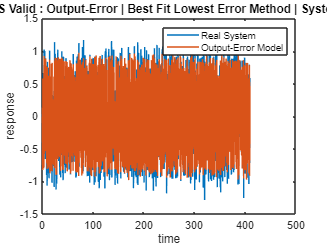



%%

oe_BestFitError_guassian = y1_val - BestFit_y_hat_guassian;
oe_VarError_guassian = y1_val - Var_y_hat_guassian;
oe_AICError_guassian = y1_val - AIC_y_hat_guassian;
oe_FTestError_guassian = y1_val - FTest_y_hat_guassian;

for k=0:N_val-1
    oe_BestFit_Ree_guassian(k+1,1) = AutoCorrelate(oe_BestFitError_guassian, k);
    oe_Var_Ree_guassian(k+1,1) = AutoCorrelate(oe_VarError_guassian, k);
    oe_AIC_Ree_guassian(k+1,1) = AutoCorrelate(oe_AICError_guassian, k);
    oe_FTest_Ree_guassian(k+1,1) = AutoCorrelate(oe_FTestError_guassian, k);
end

for k=0:N_val-1
    oe_BestFit_Rue_guassian(k+1,1) = CrossCorrelate(u1_val, oe_BestFitError_guassian, k);
    oe_Var_Rue_guassian(k+1,1) = CrossCorrelate(u1_val, oe_VarError_guassian, k);
    oe_AIC_Rue_guassian(k+1,1) = CrossCorrelate(u1_val, oe_AICError_guassian, k);
    oe_FTest_Rue_guassian(k+1,1) = CrossCorrelate(u1_val, oe_FTestError_guassian, k);
end


%%
figure(1)
plot(t_val,y1_val,t_val,BestFit_y_hat_guassian)
legend('Real System','Output-Error Model')
title(" Guassian Ident - PRBS Valid : Output-Error | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

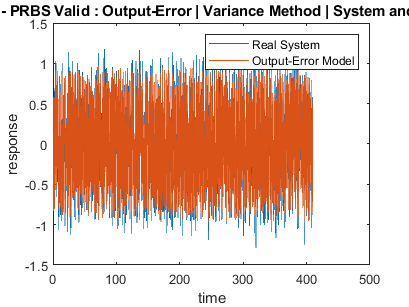


figure(2)
plot(t_val,y1_val,t_val,Var_y_hat_guassian)
legend('Real System','Output-Error Model')
title(" Guassian Ident - PRBS Valid : Output-Error | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

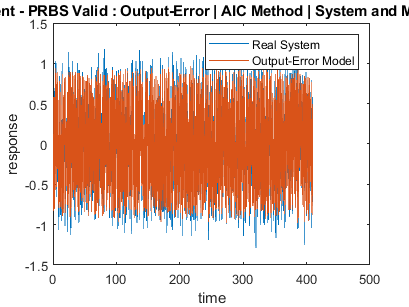


figure(3)
plot(t_val,y1_val,t_val,AIC_y_hat_guassian)
legend('Real System','Output-Error Model')
title(" Guassian Ident - PRBS Valid : Output-Error | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

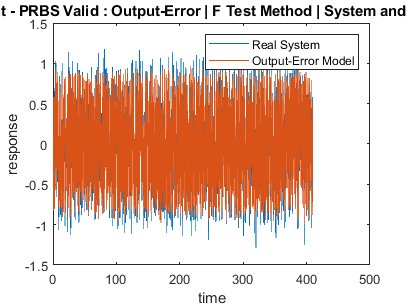


figure(4)
plot(t_val,y1_val,t_val,FTest_y_hat_guassian)
legend('Real System','Output-Error Model')
title(" Guassian Ident - PRBS Valid : Output-Error | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

% 
% %%
% 
% figure(5)
% subplot(4,1,1)
% plot(1:N_val-1,oe_BestFit_Ree_guassian(2:end), 1:N_val-1, mean(oe_BestFit_Ree_guassian(2:end))*ones(length(1:N_val-1)))
% title(" Guassian Ident - PRBS Valid : Output-Error | Best Fit Lowest Errror Method | Ree_guassian(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Ree_guassian(k)")
% 
% subplot(4,1,2)
% plot(1:N_val-1,oe_Var_Ree_guassian(2:end), 1:N_val-1, mean(oe_Var_Ree_guassian(2:end))*ones(length(1:N_val-1)))
% title(" Guassian Ident - PRBS Valid : Output-Error | Variance Method | Ree_guassian(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Ree_guassian(k)")
% 
% subplot(4,1,3)
% plot(1:N_val-1,oe_AIC_Ree_guassian(2:end), 1:N_val-1, mean(oe_AIC_Ree_guassian(2:end))*ones(length(1:N_val-1)))
% title(" Guassian Ident - PRBS Valid : Output-Error | AIC Method | Ree_guassian(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Ree_guassian(k)")
% 
% subplot(4,1,4)
% plot(1:N_val-1,oe_FTest_Ree_guassian(2:end), 1:N_val-1, mean(oe_FTest_Ree_guassian(2:end))*ones(length(1:N_val-1)))
% title(" Guassian Ident - PRBS Valid : Output-Error | F Test Method | Ree_guassian(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Ree_guassian(k)")
% 
% %%
% 
% figure(6)
% subplot(4,1,1)
% plot(1:N_val-1,oe_BestFit_Rue_guassian(2:end), 1:N_val-1, mean(oe_BestFit_Rue_guassian(2:end))*ones(length(1:N_val-1)))
% title(" Guassian Ident - PRBS Valid : Output-Error | Best Fit Lowest Errror Method | Rue_guassian(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rue_guassian(k)")
% 
% subplot(4,1,2)
% plot(1:N_val-1,oe_Var_Rue_guassian(2:end), 1:N_val-1, mean(oe_Var_Rue_guassian(2:end))*ones(length(1:N_val-1)))
% title(" Guassian Ident - PRBS Valid : Output-Error | Variance Method | Rue_guassian(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rue_guassian(k)")
% 
% subplot(4,1,3)
% plot(1:N_val-1,oe_AIC_Rue_guassian(2:end), 1:N_val-1, mean(oe_AIC_Rue_guassian(2:end))*ones(length(1:N_val-1)))
% title(" Guassian Ident - PRBS Valid : Output-Error | AIC Method | Rue_guassian(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rue_guassian(k)")
% 
% subplot(4,1,4)
% plot(1:N_val-1,oe_FTest_Rue_guassian(2:end), 1:N_val-1, mean(oe_FTest_Rue_guassian(2:end))*ones(length(1:N_val-1)))
% title(" Guassian Ident - PRBS Valid : Output-Error | F Test Method | Rue_guassian(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rue_guassian(k)")
% 



### PRBS Input - Guassian Validation

%%

% PRBS Input **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> PRBS Input Identification Begins:------------------------------\n")

>>> PRBS Input Identification Begins:------------------------------


%%

Ts = 0.1; 
t = 0:Ts:length(u2)*Ts-Ts;
t_val = 0:Ts:length(u2_val)*Ts-Ts;
N = length(y2);
N_val = length(y2_val);

data_prbs = iddata(y2,u2,Ts);


%%


fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nk = 1;
    p = na+nb;
    
    try
        sys = oe(data_prbs, [na nb nk]);
        oe_y_hat_prbs = lsim(sys, u2, t);
    catch
        break
    end

    [r2_oe, mse_oe] = rSQR(y2, oe_y_hat_prbs);

    error = y2 - oe_y_hat_prbs;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_oe, mse_oe, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_oe];
    MSEs = [MSEs; mse_oe];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=0.902599 | MSE=0.025958 | var=0.025971 | s_hat=106.325062 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.943233 | MSE=0.015129 | var=0.015144 | s_hat=61.967521 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.943272 | MSE=0.015118 | var=0.015141 | s_hat=61.924787 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.943346 | MSE=0.015099 | var=0.015128 | s_hat=61.844003 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.943374 | MSE=0.015091 | var=0.015128 | s_hat=61.813447 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.943377 | MSE=0.015091 | var=0.015135 | s_hat=61.810976 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.943455 | MSE=0.015070 | var=0.015121 | s_hat=61.725879 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.943514 | MSE=0.015054 | var=0.015113 | s_hat=61.660918 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.943676 | MSE=0.015011 | var=0.015077 | s_hat=61.483935 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=0.943632 | MSE=0.015022 | var=0.015096 | s_hat=61.531820 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=0.943682 | MSE=0.015009 | var=0.015090 | s_hat=61.477505 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=0.943714 | MSE=0.015001 | var=0.015089 | s_hat=61.442444 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.943801 | MSE=0.014977 | var=0.015073 | s_hat=61.347674 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.943696 | MSE=0.015005 | var=0.015109 | s_hat=61.462400 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.943704 | MSE=0.015003 | var=0.015114 | s_hat=61.453963 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.943929 | MSE=0.014943 | var=0.015061 | s_hat=61.208193 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.943025 | MSE=0.015184 | var=0.015311 | s_hat=62.194357 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.944077 | MSE=0.014904 | var=0.015036 | s_hat=61.047048 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=0.944113 | MSE=0.014894 | var=0.015034 | s_hat=61.006680 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.944221 | MSE=0.014866 | var=0.015012 | s_hat=60.889715 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.943920 | MSE=0.014946 | var=0.015101 | s_hat=61.217523 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=0.929689 | MSE=0.018739 | var=0.018942 | s_hat=76.753108 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.944069 | MSE=0.014906 | var=0.015075 | s_hat=61.055481 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.944080 | MSE=0.014903 | var=0.015080 | s_hat=61.042710 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.944267 | MSE=0.014853 | var=0.015037 | s_hat=60.839289 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.942470 | MSE=0.015332 | var=0.015529 | s_hat=62.801170 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.700504 | MSE=0.079818 | var=0.080884 | s_hat=326.934438 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.938939 | MSE=0.016273 | var=0.016499 | s_hat=66.655556 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.944080 | MSE=0.014903 | var=0.015117 | s_hat=61.043146 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=0.944409 | MSE=0.014815 | var=0.015036 | s_hat=60.683968 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.944543 | MSE=0.014780 | var=0.015007 | s_hat=60.537944 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.944044 | MSE=0.014913 | var=0.015149 | s_hat=61.082574 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.944219 | MSE=0.014866 | var=0.015110 | s_hat=60.891521 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.944264 | MSE=0.014854 | var=0.015105 | s_hat=60.842270 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.944264 | MSE=0.014854 | var=0.015112 | s_hat=60.842918 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.944418 | MSE=0.014813 | var=0.015078 | s_hat=60.674763 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=0.944585 | MSE=0.014768 | var=0.015040 | s_hat=60.491691 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.943844 | MSE=0.014966 | var=0.015249 | s_hat=61.301101 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.944949 | MSE=0.014672 | var=0.014956 | s_hat=60.094503 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.774757 | MSE=0.060029 | var=0.061225 | s_hat=245.879655 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.944830 | MSE=0.014703 | var=0.015004 | s_hat=60.224422 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.944776 | MSE=0.014718 | var=0.015026 | s_hat=60.283854 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.945332 | MSE=0.014570 | var=0.014882 | s_hat=59.676737 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.943826 | MSE=0.014971 | var=0.015299 | s_hat=61.320320 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.943816 | MSE=0.014974 | var=0.015310 | s_hat=61.331557 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=0.881952 | MSE=0.031461 | var=0.032184 | s_hat=128.863420 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.942191 | MSE=0.015406 | var=0.015768 | s_hat=63.105004 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=0.933224 | MSE=0.017796 | var=0.018223 | s_hat=72.893433 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.945196 | MSE=0.014606 | var=0.014964 | s_hat=59.825272 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.943774 | MSE=0.014985 | var=0.015360 | s_hat=61.377394 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=-0.022273 | MSE=0.272444 | var=0.279402 | s_hat=1115.930509 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.941309 | MSE=0.015642 | var=0.016049 | s_hat=64.067790 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=0.883015 | MSE=0.031177 | var=0.032006 | s_hat=127.702727 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=0.942396 | MSE=0.015352 | var=0.015768 | s_hat=62.881060 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=0.942028 | MSE=0.015450 | var=0.015876 | s_hat=63.283712 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=0.820368 | MSE=0.047873 | var=0.049219 | s_hat=196.089247 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=0.945294 | MSE=0.014580 | var=0.014997 | s_hat=59.717687 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.942350 | MSE=0.015364 | var=0.015812 | s_hat=62.931955 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=0.907415 | MSE=0.024675 | var=0.025407 | s_hat=101.067877 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=0.890846 | MSE=0.029090 | var=0.029968 | s_hat=119.153839 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=0.945075 | MSE=0.014638 | var=0.015087 | s_hat=59.957297 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=0.935197 | MSE=0.017270 | var=0.017810 | s_hat=70.739945 | 


-------------------------------------------------------------


>>> Degree = 63 : R2=0.945256 | MSE=0.014590 | var=0.015053 | s_hat=59.759680 | 


-------------------------------------------------------------


>>> Degree = 64 : R2=0.945506 | MSE=0.014523 | var=0.014992 | s_hat=59.487049 | 


-------------------------------------------------------------


>>> Degree = 65 : R2=0.939330 | MSE=0.016169 | var=0.016699 | s_hat=66.228283 | 


-------------------------------------------------------------


>>> Degree = 66 : R2=0.936459 | MSE=0.016934 | var=0.017498 | s_hat=69.362596 | 


-------------------------------------------------------------



fprintf("=================================================================\n")


%%


fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 64 


na = bestFitDegree;
nb = bestFitDegree;
nk = 1;
p = na+nb;

BestFitModel_prbs = oe(data_prbs, [na nb nk])

BestFitModel_prbs =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                     
                                                                                                          
  B(z) = 0.4 z^-1 + 1.667 z^-2 + 3.376 z^-3 + 4.824 z^-4 + 5.451 z^-5 + 4.889 z^-6 + 3.581 z^             
          -7 + 2.242 z^-8 + 1.279 z^-9 + 0.804 z^-10 + 0.8973 z^-11 + 1.548 z^-12 + 2.307 z^-13           
          + 2.891 z^-14 + 2.918 z^-15 + 1.933 z^-16 + 0.356 z^-17 - 1.143 z^-18 - 2.03 z^-19              
          - 1.995 z^-20 - 1.257 z^-21 - 0.3899 z^-22 - 0.01874 z^-23 - 0.2311 z^-24 - 0.8612 z^-25        
          - 1.819 z^-26 - 2.906 z^-27 - 3.855 z^-28 - 4.265 z^-29 - 3.911 z^-30 - 2.931 z^-31             
          - 1.766 z^-32 - 1.028 z^-33 - 1.013 z^-34 - 1.463 z^-35 - 1.968 z^-36 - 2.369 z^-37             
          - 2.469 z^-38 - 2.104 z^-39 - 1.412 z^-40 - 0.4556 z^-41 + 0.5126 z^-42 + 1.086 z^-43           
          + 1.083

BestFit_y_hat_prbs = lsim(BestFitModel_prbs, u2_val, t_val);
% [oe_BestFit_r2, oe_BestFit_mse] = rSQR(y_val, BestFit_y_hat);

%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 43 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 43 


na = minVarIndex;
nb = minVarIndex;
nk = 1;
p = na+nb;

oe_VarModel_prbs = oe(data_prbs, [na nb nk])

oe_VarModel_prbs =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                    
                                                                                                         
  B(z) = 0.4001 z^-1 + 0.4824 z^-2 + 0.3751 z^-3 + 0.1855 z^-4 + 0.2906 z^-5 + 0.4229 z^-6 + 0.2404 z^-7 
          - 0.1565 z^-8 - 0.2863 z^-9 - 0.3451 z^-10 - 0.2725 z^-11 - 0.4533 z^-12 - 0.4559 z^-13        
          - 0.2718 z^-14 + 0.0182 z^-15 + 0.02309 z^-16 + 0.06658 z^-17 + 0.1945 z^-18 + 0.3682 z^-19    
          + 0.3773 z^-20 + 0.3763 z^-21 + 0.4828 z^-22 + 0.3193 z^-23 + 0.1602 z^-24 + 0.07245 z^-25     
          + 0.08678 z^-26 - 0.1702 z^-27 - 0.3869 z^-28 - 0.4589 z^-29 - 0.3018 z^-30 - 0.3564 z^-31     
          - 0.4103 z^-32 - 0.3389 z^-33 - 0.02951 z^-34 + 0.2336 z^-35 + 0.181 z^-36 - 0.03987 z^-37     
         + 0.1234 z^-38 + 0.2308 z^-39 + 0.245 z^-40 + 0.002998 z^-41 - 0.06325 z^-42 + 0.02637 z^-43    
                           

Var_y_hat_prbs = lsim(oe_VarModel_prbs, u2_val, t_val);
% [oe_Var_r2, oe_Var_mse] = rSQR(y_val, Var_y_hat);

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 43 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 43 



na = minAICIndex;
nb = minAICIndex;
nk = 1;
p = na+nb;

oe_AICModel_prbs = oe(data_prbs, [na nb nk])

oe_AICModel_prbs =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                    
                                                                                                         
  B(z) = 0.4001 z^-1 + 0.4824 z^-2 + 0.3751 z^-3 + 0.1855 z^-4 + 0.2906 z^-5 + 0.4229 z^-6 + 0.2404 z^-7 
          - 0.1565 z^-8 - 0.2863 z^-9 - 0.3451 z^-10 - 0.2725 z^-11 - 0.4533 z^-12 - 0.4559 z^-13        
          - 0.2718 z^-14 + 0.0182 z^-15 + 0.02309 z^-16 + 0.06658 z^-17 + 0.1945 z^-18 + 0.3682 z^-19    
          + 0.3773 z^-20 + 0.3763 z^-21 + 0.4828 z^-22 + 0.3193 z^-23 + 0.1602 z^-24 + 0.07245 z^-25     
          + 0.08678 z^-26 - 0.1702 z^-27 - 0.3869 z^-28 - 0.4589 z^-29 - 0.3018 z^-30 - 0.3564 z^-31     
          - 0.4103 z^-32 - 0.3389 z^-33 - 0.02951 z^-34 + 0.2336 z^-35 + 0.181 z^-36 - 0.03987 z^-37     
         + 0.1234 z^-38 + 0.2308 z^-39 + 0.245 z^-40 + 0.002998 z^-41 - 0.06325 z^-42 + 0.02637 z^-43    
                           

AIC_y_hat_prbs = lsim(oe_AICModel_prbs, u2_val, t_val);
% [oe_AIC_r2, oe_AIC_mse] = rSQR(y_val, AIC_y_hat);

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.37 as


fprintf("    Degree = %d \n", winner)

    Degree = 43 



na = winner;
nb = winner;
nk = 1;
p = na+nb;

oe_FTestModel_prbs = oe(data_prbs, [na nb nk])

oe_FTestModel_prbs =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                    
                                                                                                         
  B(z) = 0.4001 z^-1 + 0.4824 z^-2 + 0.3751 z^-3 + 0.1855 z^-4 + 0.2906 z^-5 + 0.4229 z^-6 + 0.2404 z^-7 
          - 0.1565 z^-8 - 0.2863 z^-9 - 0.3451 z^-10 - 0.2725 z^-11 - 0.4533 z^-12 - 0.4559 z^-13        
          - 0.2718 z^-14 + 0.0182 z^-15 + 0.02309 z^-16 + 0.06658 z^-17 + 0.1945 z^-18 + 0.3682 z^-19    
          + 0.3773 z^-20 + 0.3763 z^-21 + 0.4828 z^-22 + 0.3193 z^-23 + 0.1602 z^-24 + 0.07245 z^-25     
          + 0.08678 z^-26 - 0.1702 z^-27 - 0.3869 z^-28 - 0.4589 z^-29 - 0.3018 z^-30 - 0.3564 z^-31     
          - 0.4103 z^-32 - 0.3389 z^-33 - 0.02951 z^-34 + 0.2336 z^-35 + 0.181 z^-36 - 0.03987 z^-37     
         + 0.1234 z^-38 + 0.2308 z^-39 + 0.245 z^-40 + 0.002998 z^-41 - 0.06325 z^-42 + 0.02637 z^-43    
                         

FTest_y_hat_prbs = lsim(oe_FTestModel_prbs, u2_val, t_val);
% [oe_FTest_r2, oe_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("=================================================================\n")



%%

[oe_BestFit_r2_prbs, oe_BestFit_mse_prbs] = rSQR(y2_val, BestFit_y_hat_prbs);
[oe_Var_r2_prbs, oe_Var_mse_prbs] = rSQR(y2_val, Var_y_hat_prbs);
[oe_AIC_r2_prbs, oe_AIC_mse_prbs] = rSQR(y2_val, AIC_y_hat_prbs);
[oe_FTest_r2_prbs, oe_FTest_mse_prbs] = rSQR(y2_val, FTest_y_hat_prbs);

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_BestFit_r2_prbs, oe_BestFit_mse_prbs)

    R2 value : 0.9382   | MSE : 0.0166 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_Var_r2_prbs, oe_Var_mse_prbs)

    R2 value : 0.9384   | MSE : 0.0166 


% fprintf("---------------------------------------------------------------\n")
% fprintf(">>> Covariance Method:\n")
% fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_Cov_r2, oe_Cov_mse)
fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_AIC_r2_prbs, oe_AIC_mse_prbs)

    R2 value : 0.9384   | MSE : 0.0166 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", oe_FTest_r2_prbs, oe_FTest_mse_prbs)

    R2 value : 0.9384   | MSE : 0.0166 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")

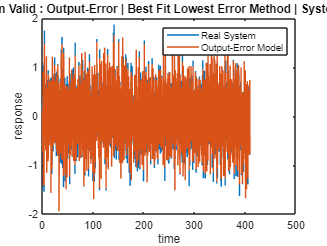



%%

oe_BestFitError_prbs = y2_val - BestFit_y_hat_prbs;
oe_VarError_prbs = y2_val - Var_y_hat_prbs;
oe_AICError_prbs = y2_val - AIC_y_hat_prbs;
oe_FTestError_prbs = y2_val - FTest_y_hat_prbs;

for k=0:N_val-1
    oe_BestFit_Ree_prbs(k+1,1) = AutoCorrelate(oe_BestFitError_prbs, k);
    oe_Var_Ree_prbs(k+1,1) = AutoCorrelate(oe_VarError_prbs, k);
    oe_AIC_Ree_prbs(k+1,1) = AutoCorrelate(oe_AICError_prbs, k);
    oe_FTest_Ree_prbs(k+1,1) = AutoCorrelate(oe_FTestError_prbs, k);
end

for k=0:N_val-1
    oe_BestFit_Rue_prbs(k+1,1) = CrossCorrelate(u2_val, oe_BestFitError_prbs, k);
    oe_Var_Rue_prbs(k+1,1) = CrossCorrelate(u2_val, oe_VarError_prbs, k);
    oe_AIC_Rue_prbs(k+1,1) = CrossCorrelate(u2_val, oe_AICError_prbs, k);
    oe_FTest_Rue_prbs(k+1,1) = CrossCorrelate(u2_val, oe_FTestError_prbs, k);
end


%%
figure(1)
plot(t_val,y2_val,t_val,BestFit_y_hat_prbs)
legend('Real System','Output-Error Model')
title(" PRBS Ident - Guassian Valid : Output-Error | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

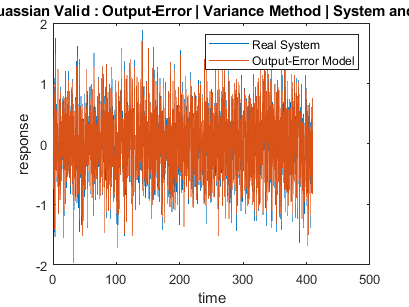


figure(2)
plot(t_val,y2_val,t_val,Var_y_hat_prbs)
legend('Real System','Output-Error Model')
title(" PRBS Ident - Guassian Valid : Output-Error | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

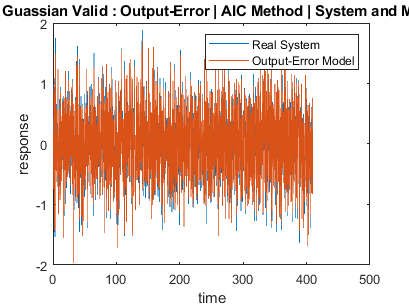


figure(3)
plot(t_val,y2_val,t_val,AIC_y_hat_prbs)
legend('Real System','Output-Error Model')
title(" PRBS Ident - Guassian Valid : Output-Error | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

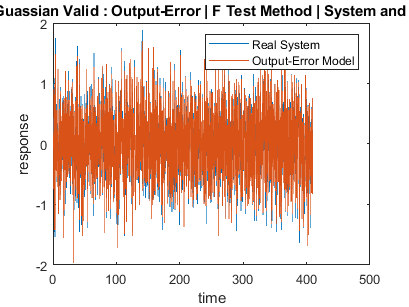


figure(4)
plot(t_val,y2_val,t_val,FTest_y_hat_prbs)
legend('Real System','Output-Error Model')
title(" PRBS Ident - Guassian Valid : Output-Error | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")


% %%
% 
% figure(5)
% subplot(4,1,1)
% plot(1:N_val-1,oe_BestFit_Ree_prbs(2:end), 1:N_val-1, mean(oe_BestFit_Ree_prbs(2:end))*ones(length(1:N_val-1)))
% title(" PRBS Ident - Guassian Valid : Output-Error | Best Fit Lowest Errror Method | Ree_prbs(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Ree_prbs(k)")
% 
% subplot(4,1,2)
% plot(1:N_val-1,oe_Var_Ree_prbs(2:end), 1:N_val-1, mean(oe_Var_Ree_prbs(2:end))*ones(length(1:N_val-1)))
% title(" PRBS Ident - Guassian Valid : Output-Error | Variance Method | Ree_prbs(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Ree_prbs(k)")
% 
% subplot(4,1,3)
% plot(1:N_val-1,oe_AIC_Ree_prbs(2:end), 1:N_val-1, mean(oe_AIC_Ree_prbs(2:end))*ones(length(1:N_val-1)))
% title(" PRBS Ident - Guassian Valid : Output-Error | AIC Method | Ree_prbs(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Ree_prbs(k)")
% 
% subplot(4,1,4)
% plot(1:N_val-1,oe_FTest_Ree_prbs(2:end), 1:N_val-1, mean(oe_FTest_Ree_prbs(2:end))*ones(length(1:N_val-1)))
% title(" PRBS Ident - Guassian Valid : Output-Error | F Test Method | Ree_prbs(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Ree_prbs(k)")
% 
% %%
% 
% figure(6)
% subplot(4,1,1)
% plot(1:N_val-1,oe_BestFit_Rue_prbs(2:end), 1:N_val-1, mean(oe_BestFit_Rue_prbs(2:end))*ones(length(1:N_val-1)))
% title(" PRBS Ident - Guassian Valid : Output-Error | Best Fit Lowest Errror Method | Rue_prbs(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rue_prbs(k)")
% 
% subplot(4,1,2)
% plot(1:N_val-1,oe_Var_Rue_prbs(2:end), 1:N_val-1, mean(oe_Var_Rue_prbs(2:end))*ones(length(1:N_val-1)))
% title(" PRBS Ident - Guassian Valid : Output-Error | Variance Method | Rue_prbs(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rue_prbs(k)")
% 
% subplot(4,1,3)
% plot(1:N_val-1,oe_AIC_Rue_prbs(2:end), 1:N_val-1, mean(oe_AIC_Rue_prbs(2:end))*ones(length(1:N_val-1)))
% title(" PRBS Ident - Guassian Valid : Output-Error | AIC Method | Rue_prbs(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rue_prbs(k)")
% 
% subplot(4,1,4)
% plot(1:N_val-1,oe_FTest_Rue_prbs(2:end), 1:N_val-1, mean(oe_FTest_Rue_prbs(2:end))*ones(length(1:N_val-1)))
% title(" PRBS Ident - Guassian Valid : Output-Error | F Test Method | Rue_prbs(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rue_prbs(k)")

